clc
clear 
% close all

defines

load s20/data420.mat
plot(t,h);
hold on
plot(t,g)
s = tf('s');

z priklady_metoda_momentov

T_vz = t(2) - t(1);
M_count = 3; 
M_i = zeros(1,M_count);
for i = 1:4
    M_i(i) = sum(((t.^(i-1)).*(h')).*T_vz);
end
M = [0 0 1;M_i(1) 0 0; -M_i(2) M_i(1) 0];
m = [M_i(1); M_i(2); -M_i(3)/2];
theta_hat = inv(M)*m;
F = (theta_hat(3))/(theta_hat(2)*s^2+theta_hat(1)*s+1) %bruuh theta(1) je a2 ???

F =
 
           1.102
  ------------------------
  0.9989 s^2 + 2.582 s + 1
 
Continuous-time transfer function.
Model Properties


calc 

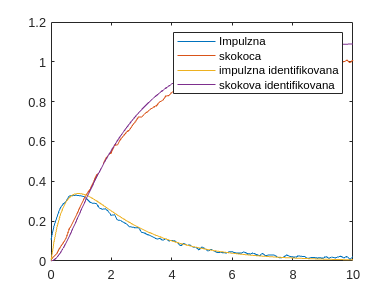

h_model = impulse(F,t);
g_model = step(F,t);
plot(t, h_model);
plot(t, g_model);
legend("Impulzna","skokoca","impulzna identifikovana","skokova identifikovana")